% Prepare the data and the sampling frequency
fs = interictal_segment_1.sampling_frequency;
data = interictal_segment_1.data;
nChans = size(interictal_segment_1.channels, 2);

# Compute the correlation features

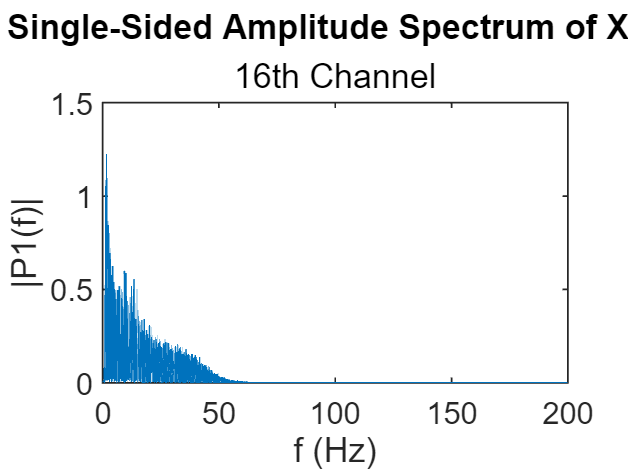

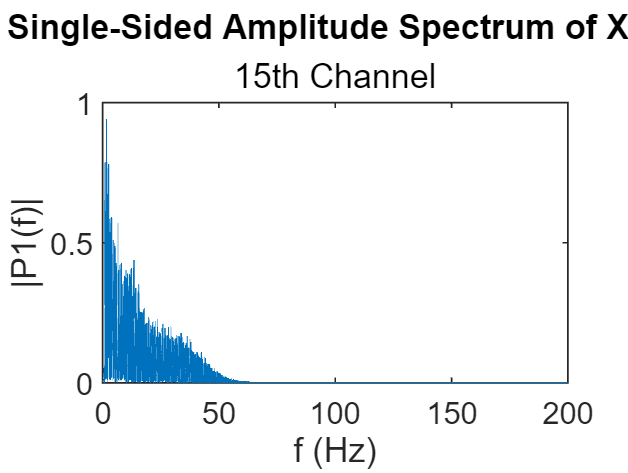

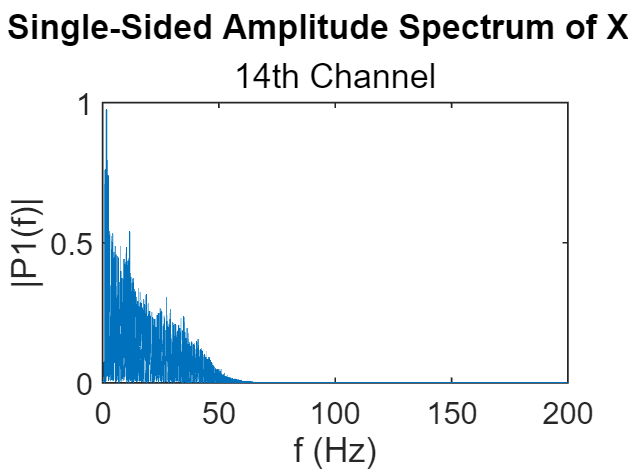

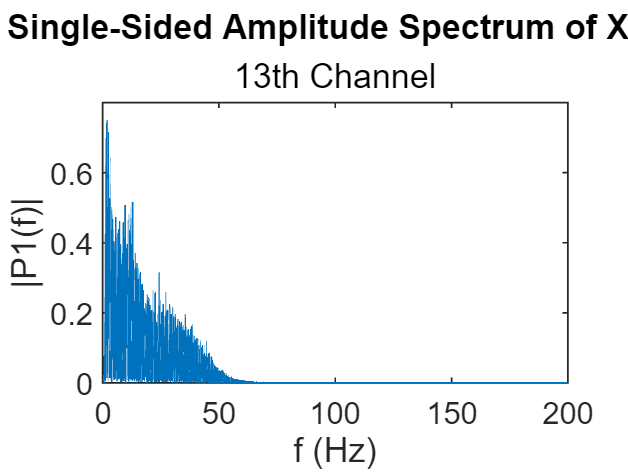

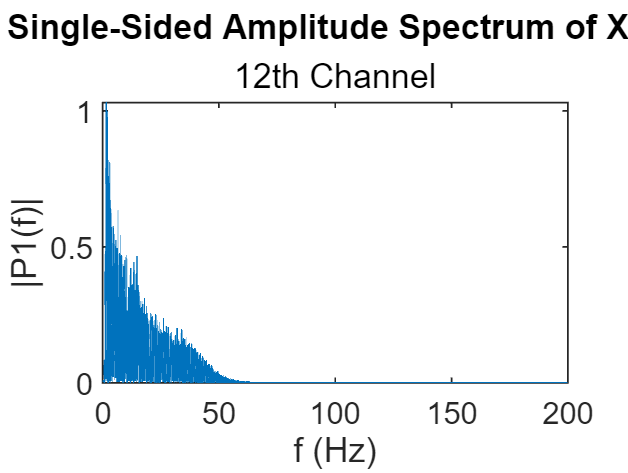

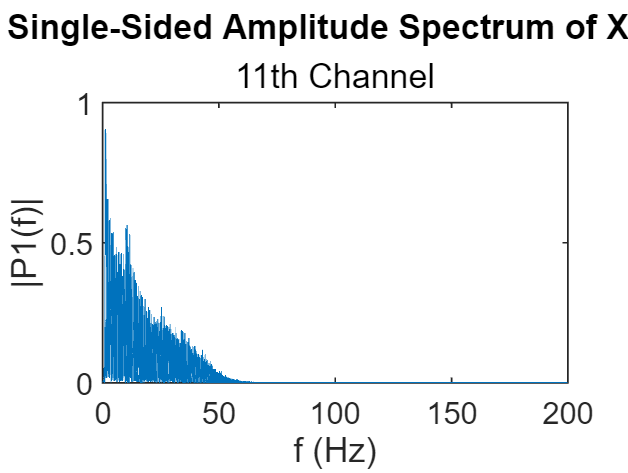

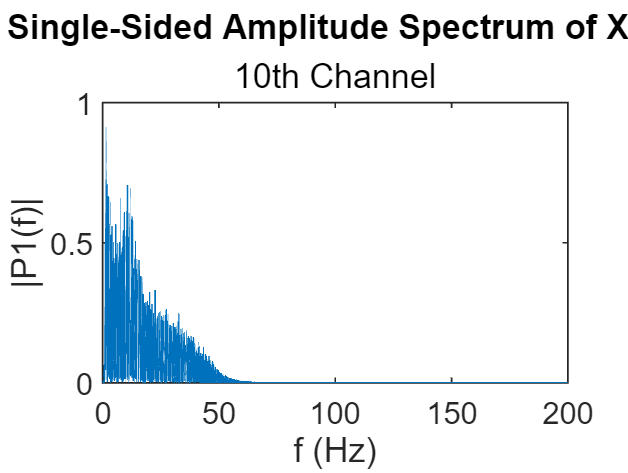

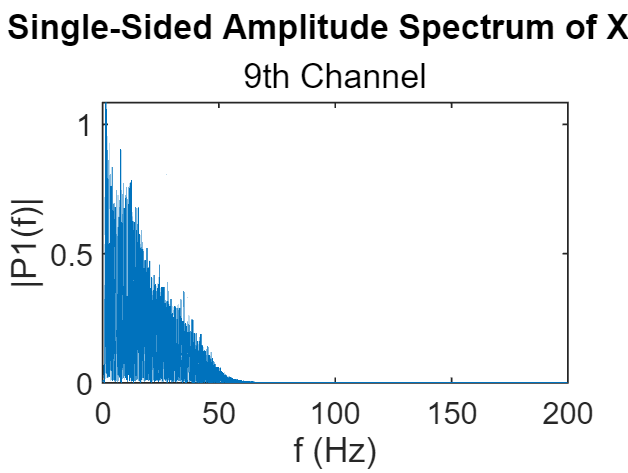

% Butterworth filter
y_td = butterfiltfilt(data, [1, 47], 400);
% Store the frequency domain data
filtered_fft = zeros(size(y_td));
% Store the single side amplitude spectrum
P1_data = zeros(nChans, size(data,2)/2+1, 'single');
% Length of original data
L = size(interictal_segment_1.data,2);

parfor c=1:size(filtered_fft, 1)
    % Fourier transform
    filtered_fft(c, :) =  fft(y_td(c, :))
    y_fd = filtered_fft(c, :);

    % Double side
    P2 = abs(y_fd/L);
    % Single side
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);

    f_fft = fs*(0:(L/2))/L;
    figure
    plot(f_fft,P1) 
    title('Single-Sided Amplitude Spectrum of X(t)')
    subtitle(sprintf('%dth Channel', c))
    xlabel('f (Hz)')
    ylabel('|P1(f)|')
    P1_data(c, :) = P1
end    

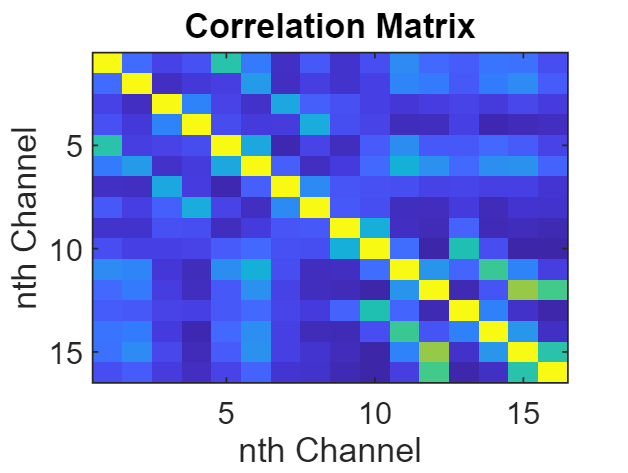

% Compute the corraltion matrix
corrs = corr(P1_data');
figure
% Visualize the matrix
imagesc(corrs)
xlabel("nth Channel")
ylabel("nth Channel")
title("Correlation Matrix")

% Assign field values to feature structure
feature = struct();
feature.corr_mat = corrs;
feature.corr_mean = mean(corrs);
feature.corr_std = std(corrs);
feature.corr_sum = sum(corrs);

# Compute the Band Power Features

% Define the bands Limits
bLims = [[1;3], [4;7], [8;9], [10;12], [13;17], [18;30],...
    [31;40], [41;50], [51;70], [71;150], [151;250]]; 
% Number of Bands
nBands = size(bLims,2);
% Store the bands values
bands_value = zeros(nBands, 16, 'single');
% Store the Max band value Per Channel
max_bands =  zeros(1, 16, 'single');


for c=1:size(filtered_fft, 1)
    % Fourier transform
    filtered_fft(c, :) =  fft(y_td(c, :));
    y_fd = filtered_fft(c, :);

    % Double side
    P2 = abs(y_fd/L);
    % Single side
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);

    f_fft = fs*(0:(L/2))/L;

    for b = 1:nBands
        bIdx = f_fft>=bLims(1,b) & f_fft<=bLims(2,b);
        
        mPower = mean(P1(bIdx));
        
        bands_value(b, c) = mPower;

    end

    max_bands(1,c) = max(bands_value(:,c));

end  

% Max_band average
max_bandavg = mean(max_bands);
% Add field values
feature.bands_value = bands_value;

feature = struct with fields:
       corr_mat: [16×16 single]
      corr_mean: [0.8048 0.7974 0.7885 0.7845 0.8012 0.8125 0.7890 0.7879 0.7829 0.7961 0.8111 0.8062 0.7955 0.8023 0.8099 0.7921]
       corr_std: [0.0599 0.0600 0.0611 0.0632 0.0632 0.0591 0.0616 0.0627 0.0636 0.0652 0.0641 0.0734 0.0628 0.0653 0.0711 0.0716]
       corr_sum: [12.8765 12.7588 12.6163 12.5524 12.8198 12.9997 12.6242 12.6061 12.5257 12.7371 12.9769 12.8999 12.7285 12.8361 12.9590 12.6728]
    bands_value: [11×16 single]


feature.max_bands = max_bands;

feature = struct with fields:
       corr_mat: [16×16 single]
      corr_mean: [0.8048 0.7974 0.7885 0.7845 0.8012 0.8125 0.7890 0.7879 0.7829 0.7961 0.8111 0.8062 0.7955 0.8023 0.8099 0.7921]
       corr_std: [0.0599 0.0600 0.0611 0.0632 0.0632 0.0591 0.0616 0.0627 0.0636 0.0652 0.0641 0.0734 0.0628 0.0653 0.0711 0.0716]
       corr_sum: [12.8765 12.7588 12.6163 12.5524 12.8198 12.9997 12.6242 12.6061 12.5257 12.7371 12.9769 12.8999 12.7285 12.8361 12.9590 12.6728]
    bands_value: [11×16 single]
      max_bands: [0.5434 0.4475 0.3277 0.3627 0.4014 0.2474 0.2102 0.2490 0.3669 0.2734 0.2460 0.3077 0.2622 0.2511 0.2641 0.3480]


feature.max_bands_avg = max_bandavg;

feature = struct with fields:
         corr_mat: [16×16 single]
        corr_mean: [0.8048 0.7974 0.7885 0.7845 0.8012 0.8125 0.7890 0.7879 0.7829 0.7961 0.8111 0.8062 0.7955 0.8023 0.8099 0.7921]
         corr_std: [0.0599 0.0600 0.0611 0.0632 0.0632 0.0591 0.0616 0.0627 0.0636 0.0652 0.0641 0.0734 0.0628 0.0653 0.0711 0.0716]
         corr_sum: [12.8765 12.7588 12.6163 12.5524 12.8198 12.9997 12.6242 12.6061 12.5257 12.7371 12.9769 12.8999 12.7285 12.8361 12.9590 12.6728]
      bands_value: [11×16 single]
        max_bands: [0.5434 0.4475 0.3277 0.3627 0.4014 0.2474 0.2102 0.2490 0.3669 0.2734 0.2460 0.3077 0.2622 0.2511 0.2641 0.3480]
    max_bands_avg: 0.3193
